% Below code is leveraged from prof. harris' problem statement

fs = 32; % In kHz
f0 = 4;  % In kHz
f1 = 8;  % In kHz
UPSAMPLE_RATIO = 32;
NUMFFT = 4096;

NUM_BITS_PER_ASCII_CHAR = 7;  % ASCII uses 7 bits per character

name = 'Shantonu Mandal';

% Convert letters to decimal ASCII
decimal_in = abs(name);

% Convert decimal to binary
% NOTE: de2bi no longer seems to be supported on Matlab 2025b. Using the
% recommended int2bit function. int2bit returns the binary data in a manner
% that we do not need to transpose it while passing it to reshape.
%binary_in = de2bi(decimal_in);
binary_in  = int2bit(decimal_in, NUM_BITS_PER_ASCII_CHAR);

% Form a single binary vector
bb1 = reshape(binary_in, 1, length(name) * NUM_BITS_PER_ASCII_CHAR);

% Prepare to up-sample 1-to-32
bb2 = zeros(1, UPSAMPLE_RATIO * length(name) * NUM_BITS_PER_ASCII_CHAR);

% Zero-pack binary data 1-to-32
bb2(1 : UPSAMPLE_RATIO : length(bb2)) = bb1;

% Extend binary samples 1-to-32
bb2 = filter(ones(1, UPSAMPLE_RATIO), 1, bb2);

% Below is equivalent to 4*bb2 + 4, just generalized for f0 & f1
ff  = ((f1 - f0) * bb2) + f0;     % Scale and shift to 4 & 8 kHz
phs = filter(1, [1 -1], ff / fs); % Integrate frequency to form phase
xx  = sin(2 * pi * phs);          % Form time signal with frequency profile

h1 = (1 / 32) * exp(1j * 2 * pi * (0 : 31) * f0 / fs); % Complex weight matched filter
h2 = (1 / 32) * exp(1j * 2 * pi * (0 : 31) * f1 / fs); % Complex weight matched filter


### Part 1

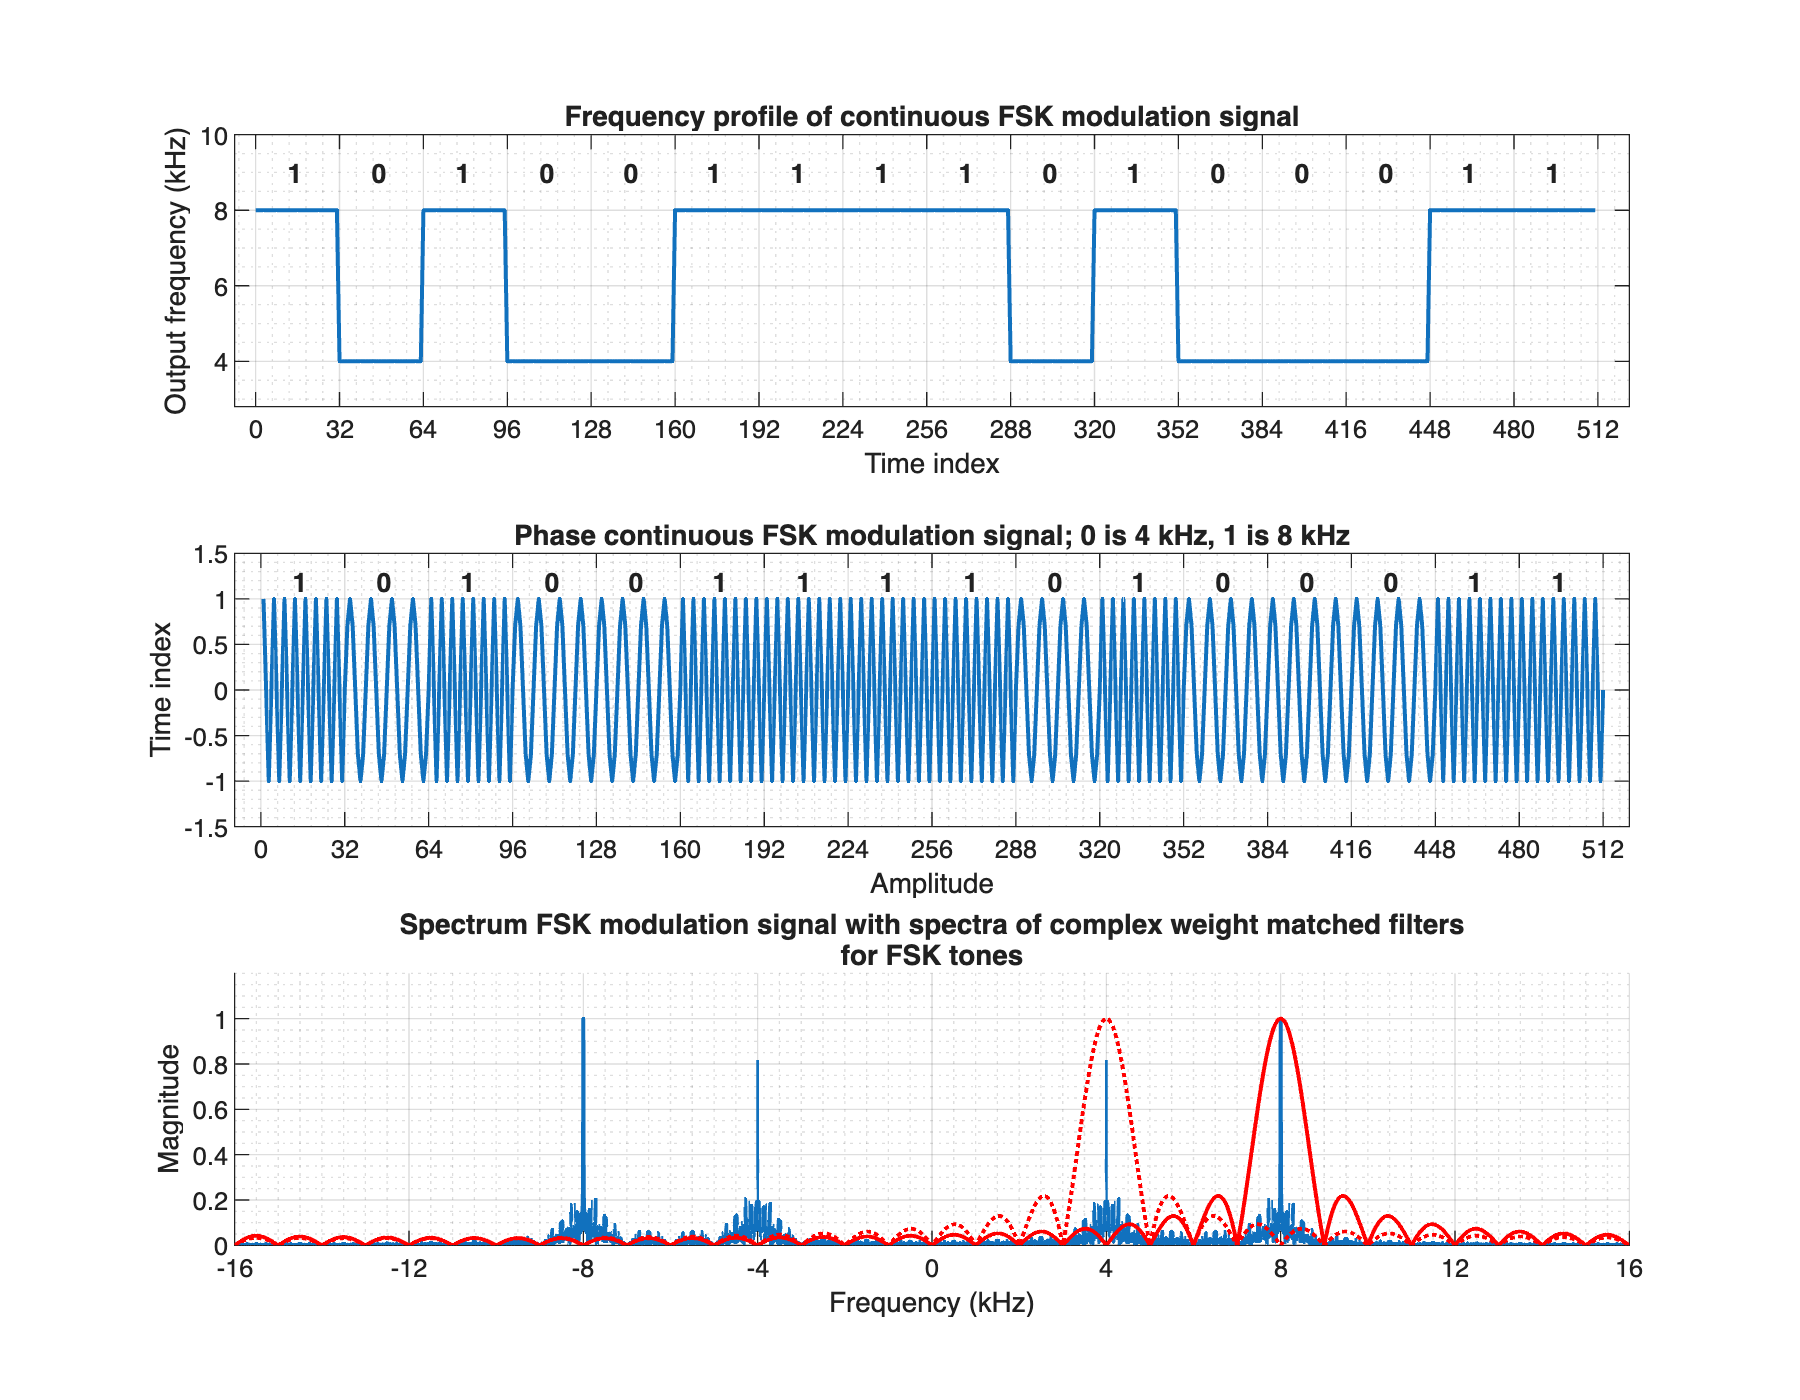

% On three subplots, plot the frequency profile (ff), the time series (xx),
% and the linear magnitude spectrum scaled for unity maximum gain. On the
% spectrum subplot also show the spectra of the two matched filters.

PLOT_MAX_LEN = 512;
figure("Position", [0 0 900 700]);
subplot(3, 1, 1);
plot(0 : PLOT_MAX_LEN - 1, ff(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, 0.2 * min(f0, f1), max(f0, f1)] + 2);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Overlay the binary sequence text
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(f0, f1) + 1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i), y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Frequency profile of continuous FSK modulation signal");
xlabel("Time index"); ylabel("Output frequency (kHz)");

subplot(3, 1, 2);
plot(xx(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, -1.5, 1.5]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
DLY = 0;
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(xx) + 0.2) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Phase continuous FSK modulation signal; 0 is 4 kHz, 1 is 8 kHz");
xlabel("Amplitude"); ylabel("Time index");

f_h1 = fftshift(abs(fft(h1, NUMFFT)));
f_h2 = fftshift(abs(fft(h2, NUMFFT)));

% Get the spectrum of tones and normalize to unity gain
f_x = fftshift(abs(fft(xx, NUMFFT)));
scl = max(f_x);
f_x = f_x / scl;
f = (-0.5 : 1/NUMFFT : 0.5 - 1/NUMFFT) * fs;
subplot(3, 1, 3);
hold on;
plot(f, f_x, "LineWidth", 1.5);
plot(f, f_h1, ":r", "LineWidth", 1.5);
plot(f, f_h2, "r", "LineWidth", 1.5);
hold off;
grid on; grid minor; axis on;
axis([-fs/2, fs/2, 0, 1.2]);
xticks(-fs/2 : 4 : fs/2);
title(...
  {...
    "Spectrum FSK modulation signal with spectra of complex weight matched filters", ...
    "for FSK tones"
  });
xlabel("Frequency (kHz)"); ylabel("Magnitude");

### Part 2

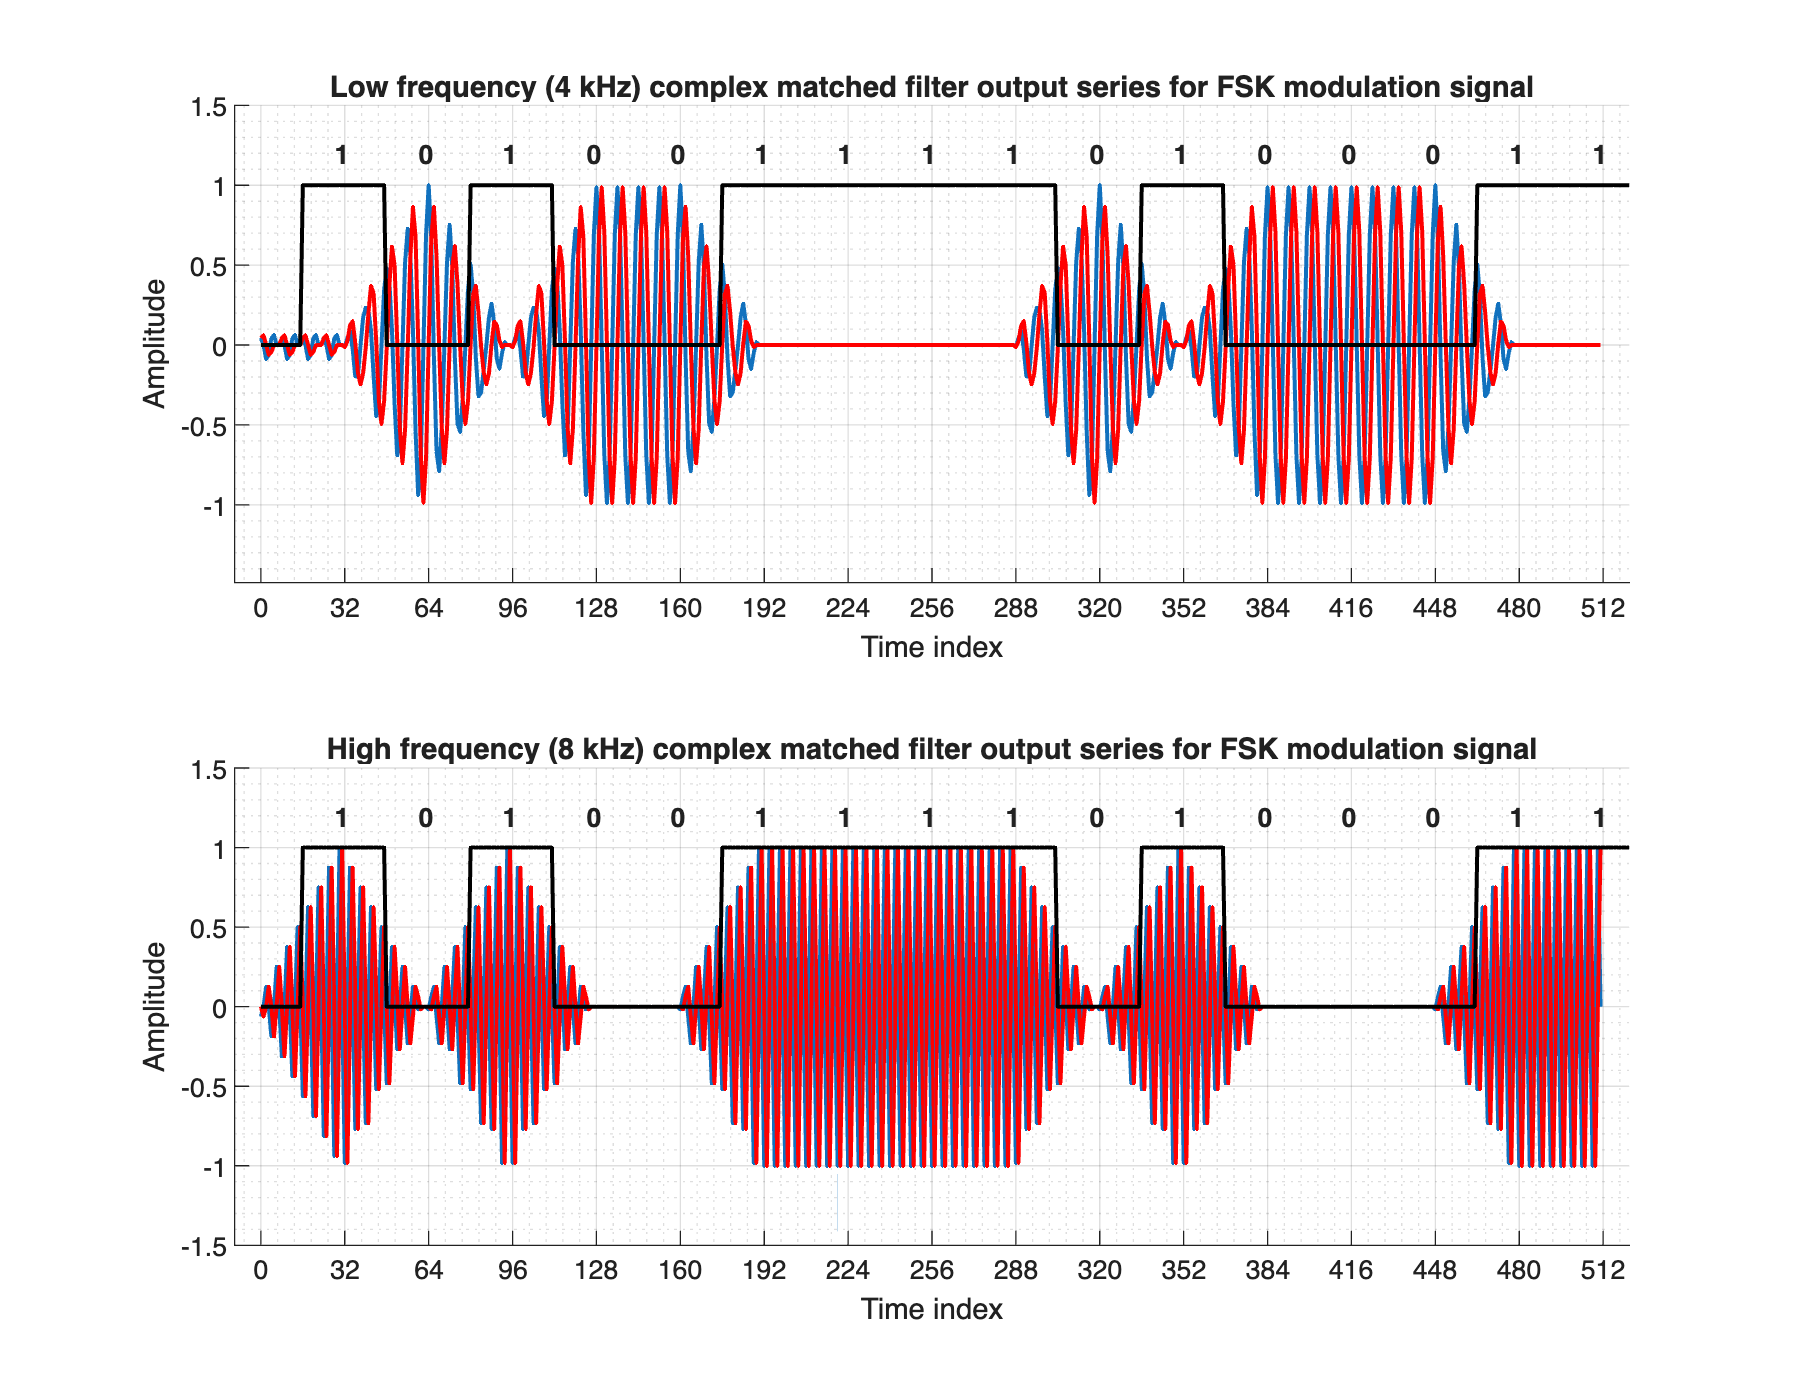

% Pass the FSK signal through the two matched filters and on two subplots
% plot the output series from filter h1 and the output series from filter
% h2. On the same subplots plot an overlay of the binary sequence (bb1)
% with 12-sample offsets to align with the filter output series.

y1 = filter(h1, 1, xx);
y2 = filter(h2, 1, xx);

scl = max(y1);
y1_scaled = y1 / scl;

scl = max(y2);
y2_scaled = y2 / scl;

figure("Position", [0 0 900 700]);
% Delay is half the length of the filter
DLY = length(h1) / 2;
y = real(y1_scaled);
y_tmp = imag(y1_scaled);
subplot(2, 1, 1);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(0 : PLOT_MAX_LEN - 1, y_tmp(1 : PLOT_MAX_LEN), "r", "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "k", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.5, max(y) + 0.5]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.2) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  sprintf(...
    "Low frequency (%d kHz) complex matched filter output series for " + ...
    "FSK modulation signal", f0));
xlabel("Time index"); ylabel("Amplitude");

y = real(y2_scaled);
y_tmp = imag(y2_scaled);
subplot(2, 1, 2);
hold on;
% Real part in blue & imaginary part in red
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(0 : PLOT_MAX_LEN - 1, y_tmp(1 : PLOT_MAX_LEN), "r", "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "k", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.5, max(y) + 0.5]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.2) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  sprintf(...
    "High frequency (%d kHz) complex matched filter output series for " + ...
    "FSK modulation signal", f1));
xlabel("Time index"); ylabel("Amplitude");

### Part 3

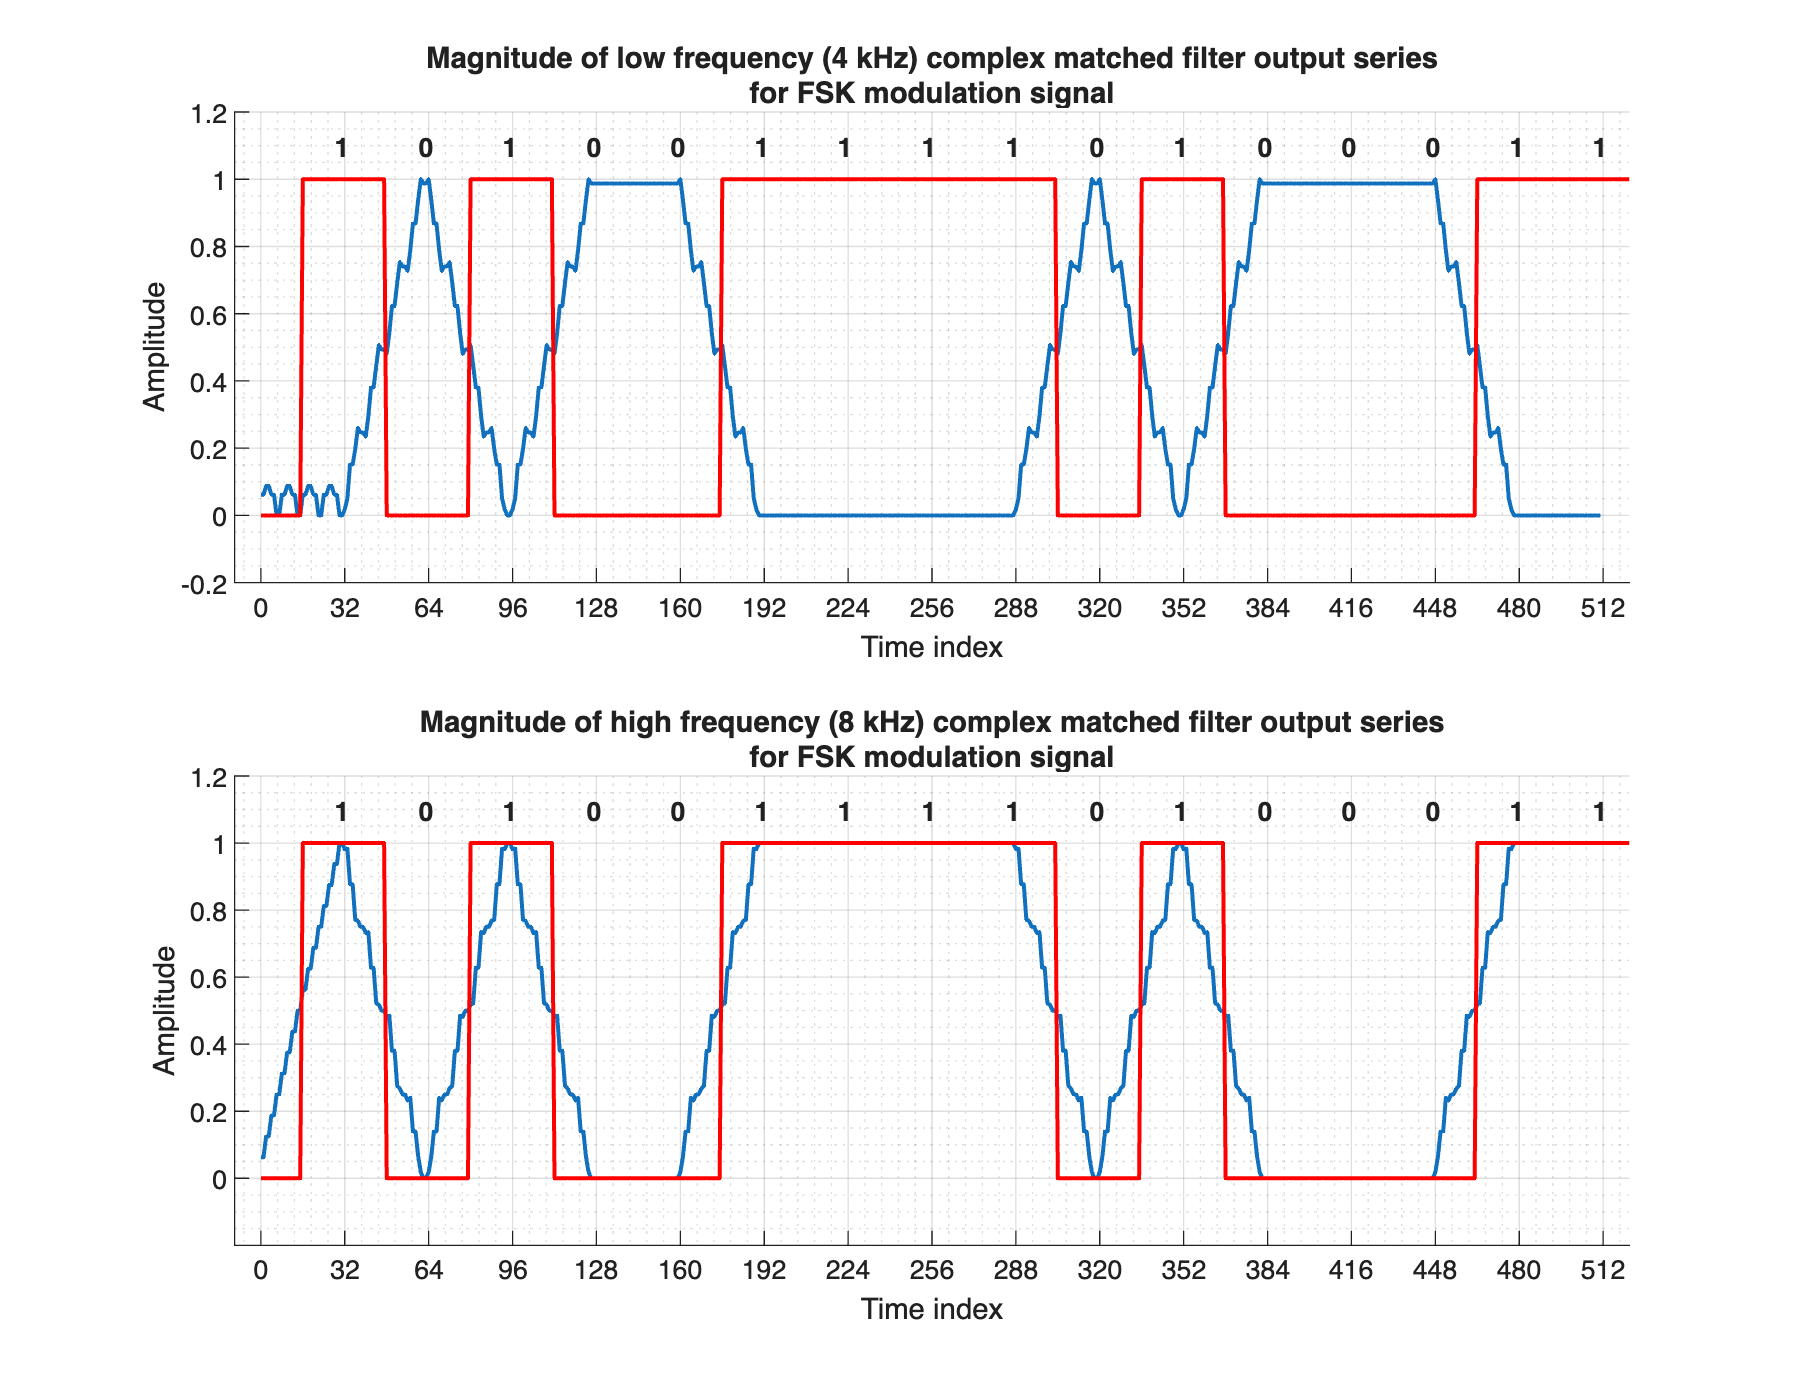

% In order to detect the presence or absence of each tone the tone must be
% detected. This is done by taking the magnitude of the filter output. On
% two subplots, plot the magnitude of the output series from filter h1 and
% the output series from filter h2. Include on these subplots the overlay
% of binary sequence (bb1).

figure("Position", [0 0 900 700]);
y = abs(y1_scaled);
subplot(2, 1, 1);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Magnitude of low frequency (%d kHz) complex matched filter output series", f0), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");

y = abs(y2_scaled);
subplot(2, 1, 2);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Magnitude of high frequency (%d kHz) complex matched filter output series", f1), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");

### Part 4

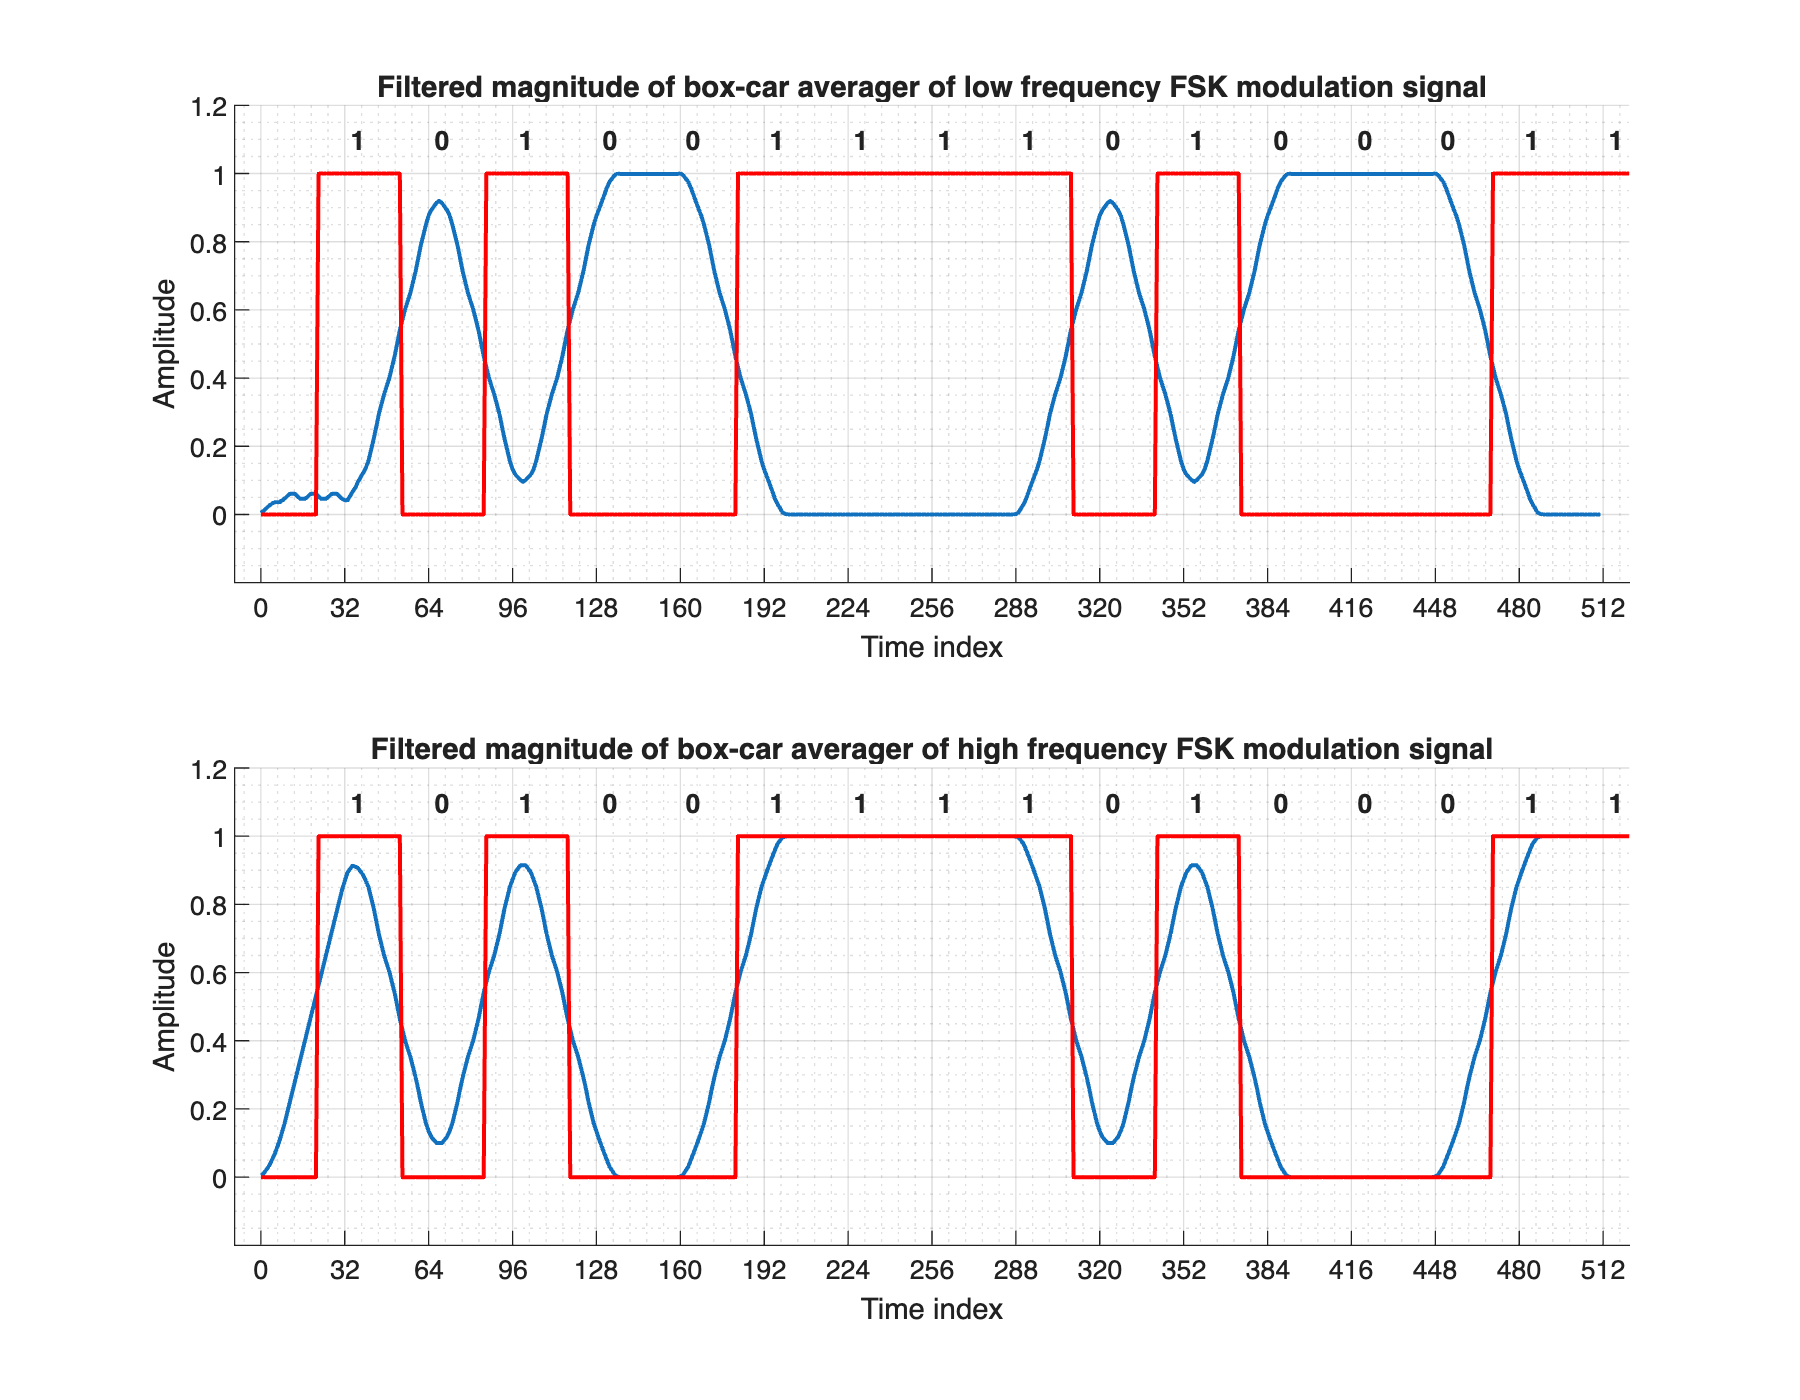

% Noting that the magnitude of the filter outputs displayed in the previous
% subplots is not a smooth function we respond with a post detection averager
% to obtain an improved detection. We perform the post detection average of
% the filter magnitude with a 12-tap box-car averager (ones(1,12)/8;). On
% two subplots plot the output series obtained averaging the detected signals
% from filters h1and from filter h2. On the same subplots plot an overlay of
% the binary sequence (bb1) with a 24-sample offset to align with the filter
% output series.

h3 = ones(1, 12) / 8;

y_lo_smooth = filter(h3, 1, abs(y1_scaled));
y_hi_smooth = filter(h3, 1, abs(y2_scaled));

scl = max(y_lo_smooth);
y_lo_smooth_scaled = y_lo_smooth / scl;

scl = max(y_hi_smooth);
y_hi_smooth_scaled = y_hi_smooth / scl;

figure("Position", [0 0 900 700]);
% Add the previous delay to the box car avg filter delay
DLY = DLY + length(h3) / 2;
y = y_lo_smooth_scaled;
subplot(2, 1, 1);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Filtered magnitude of box-car averager of low frequency FSK modulation signal");
xlabel("Time index"); ylabel("Amplitude");

y = y_hi_smooth_scaled;
subplot(2, 1, 2);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Filtered magnitude of box-car averager of high frequency FSK modulation signal");
xlabel("Time index"); ylabel("Amplitude");

### Part 5

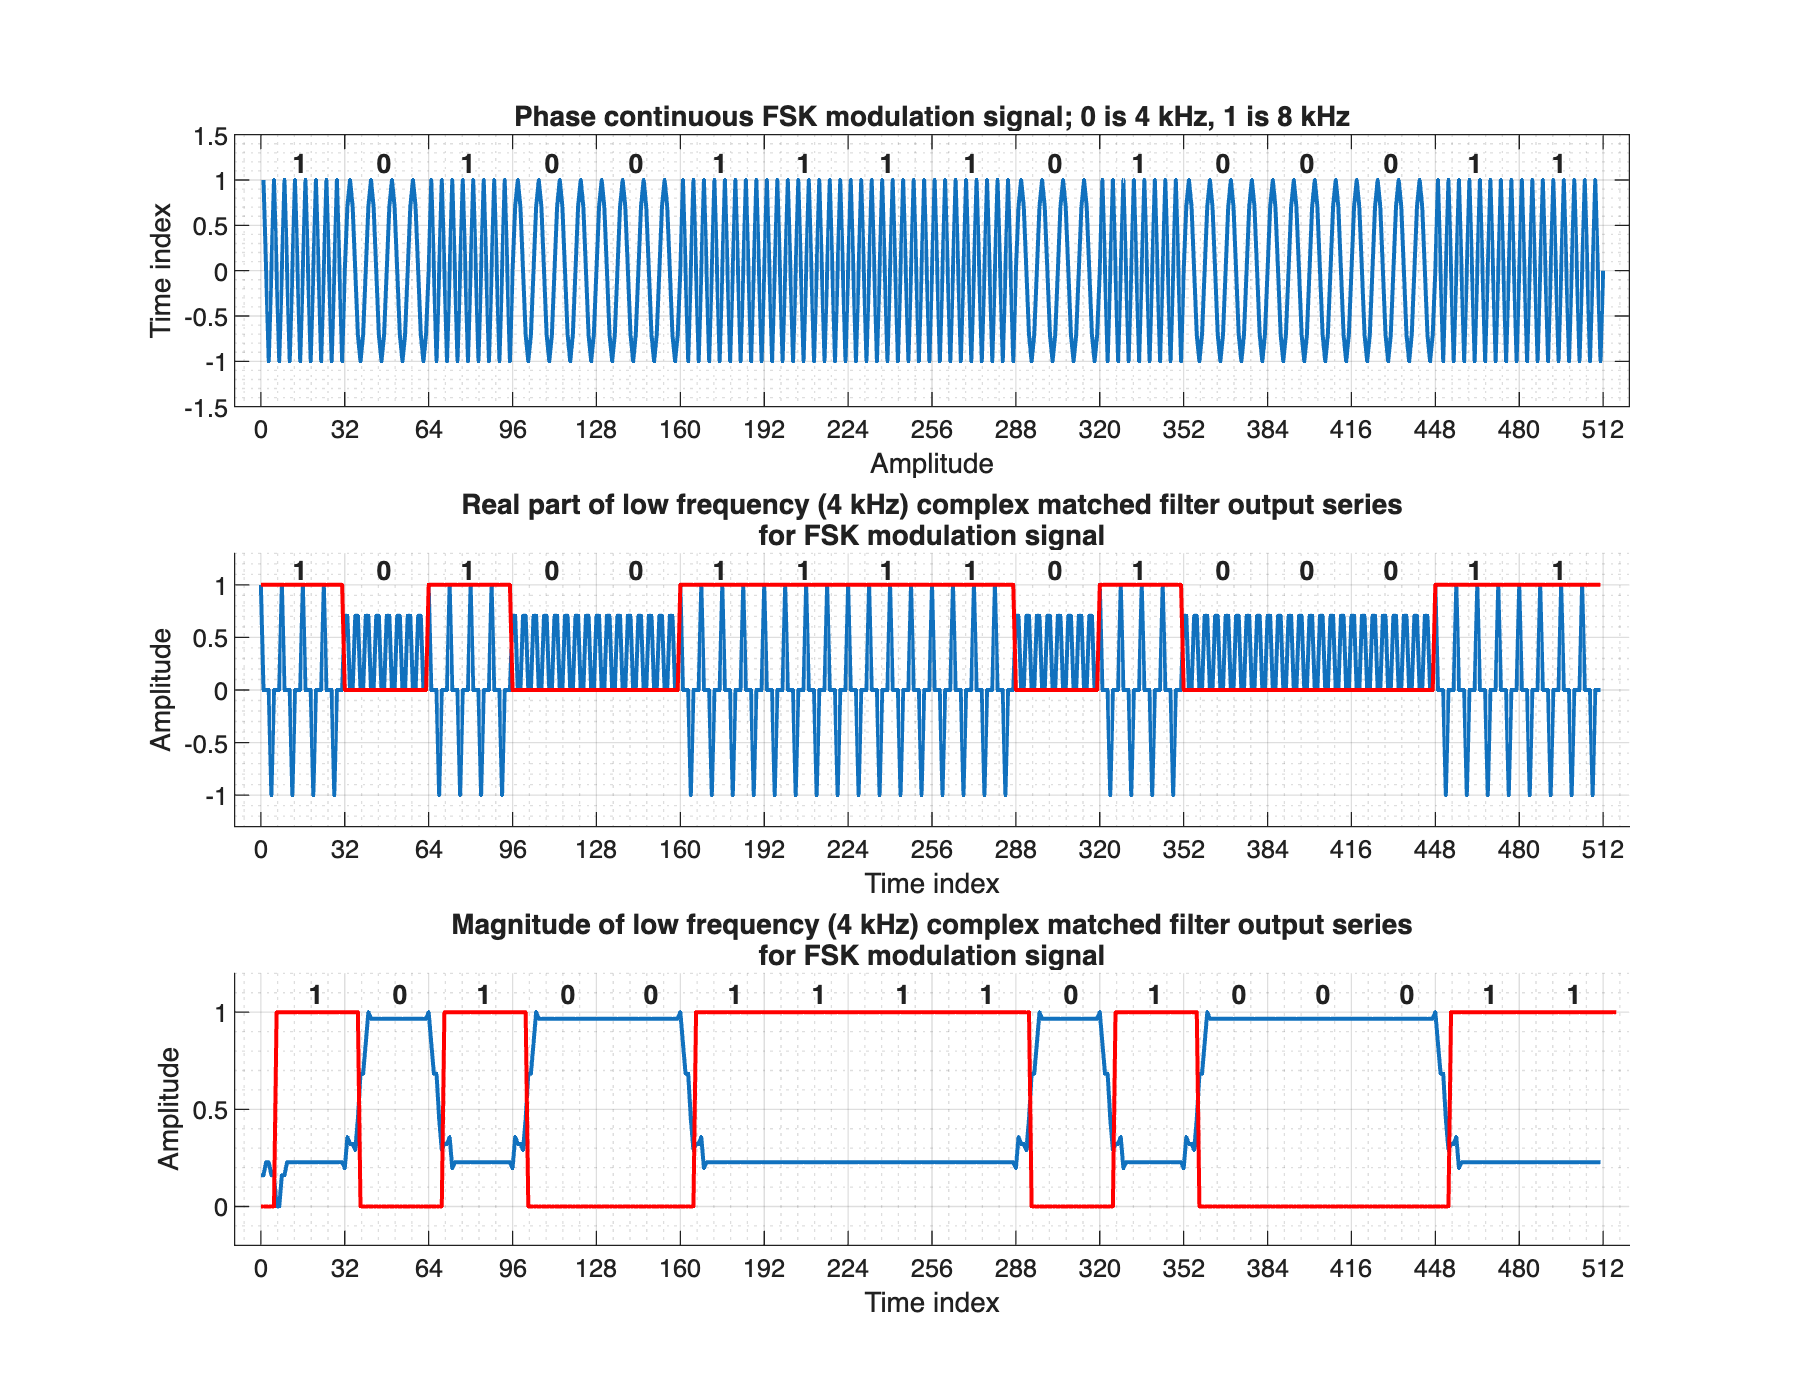

% An alternate detection scheme translates the two FSK tones to baseband
% with complex down converters of the form:
% yy1=xx.*exp(-j*2*pi*(0:length(xx)-1)*4/32);
% yy2=xx.*exp(-j*2*pi*(0:length(xx)-1)*8/32);

% These complex base-band signals are filtered with boxcar averages of the
% form:
% yy3=filter(ones(1,12)/8,yy1);
% yy4=filter(ones(1,12)/8,yy2);

% On two subplots plot the magnitude of output series obtained from the
% filters described above. On the same subplots plot an overlay of the
% binary sequence (bb1) with a 6-sample offset to align with the filter
% output series.

yy1 = xx .* exp(-1j * 2 * pi * (0 : length(xx) - 1) * f0 / fs);
yy2 = xx .* exp(-1j * 2 * pi * (0 : length(xx) - 1) * f1 / fs);

yy3 = filter(h3, 1, yy1);
yy4 = filter(h3, 1, yy2);

scl = max(yy3);
yy3_scaled = yy3 / scl;

scl = max(yy4);
yy4_scaled = yy4 / scl;

figure("Position", [0 0 900 700]);
subplot(3, 1, 1);
plot(xx(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, -1.5, 1.5]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(xx) + 0.2) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i), y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Phase continuous FSK modulation signal; 0 is 4 kHz, 1 is 8 kHz");
xlabel("Amplitude"); ylabel("Time index");

subplot(3, 1, 2);
y = real(yy1);
DLY = 0;
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.3, max(y) + 0.3]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.15) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Real part of low frequency (%d kHz) complex matched filter output series", f0), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");
DLY = length(h3) / 2; % Half of the length of box car average filter
y = abs(yy3_scaled);
subplot(3, 1, 3);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Magnitude of low frequency (%d kHz) complex matched filter output series", f0), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");

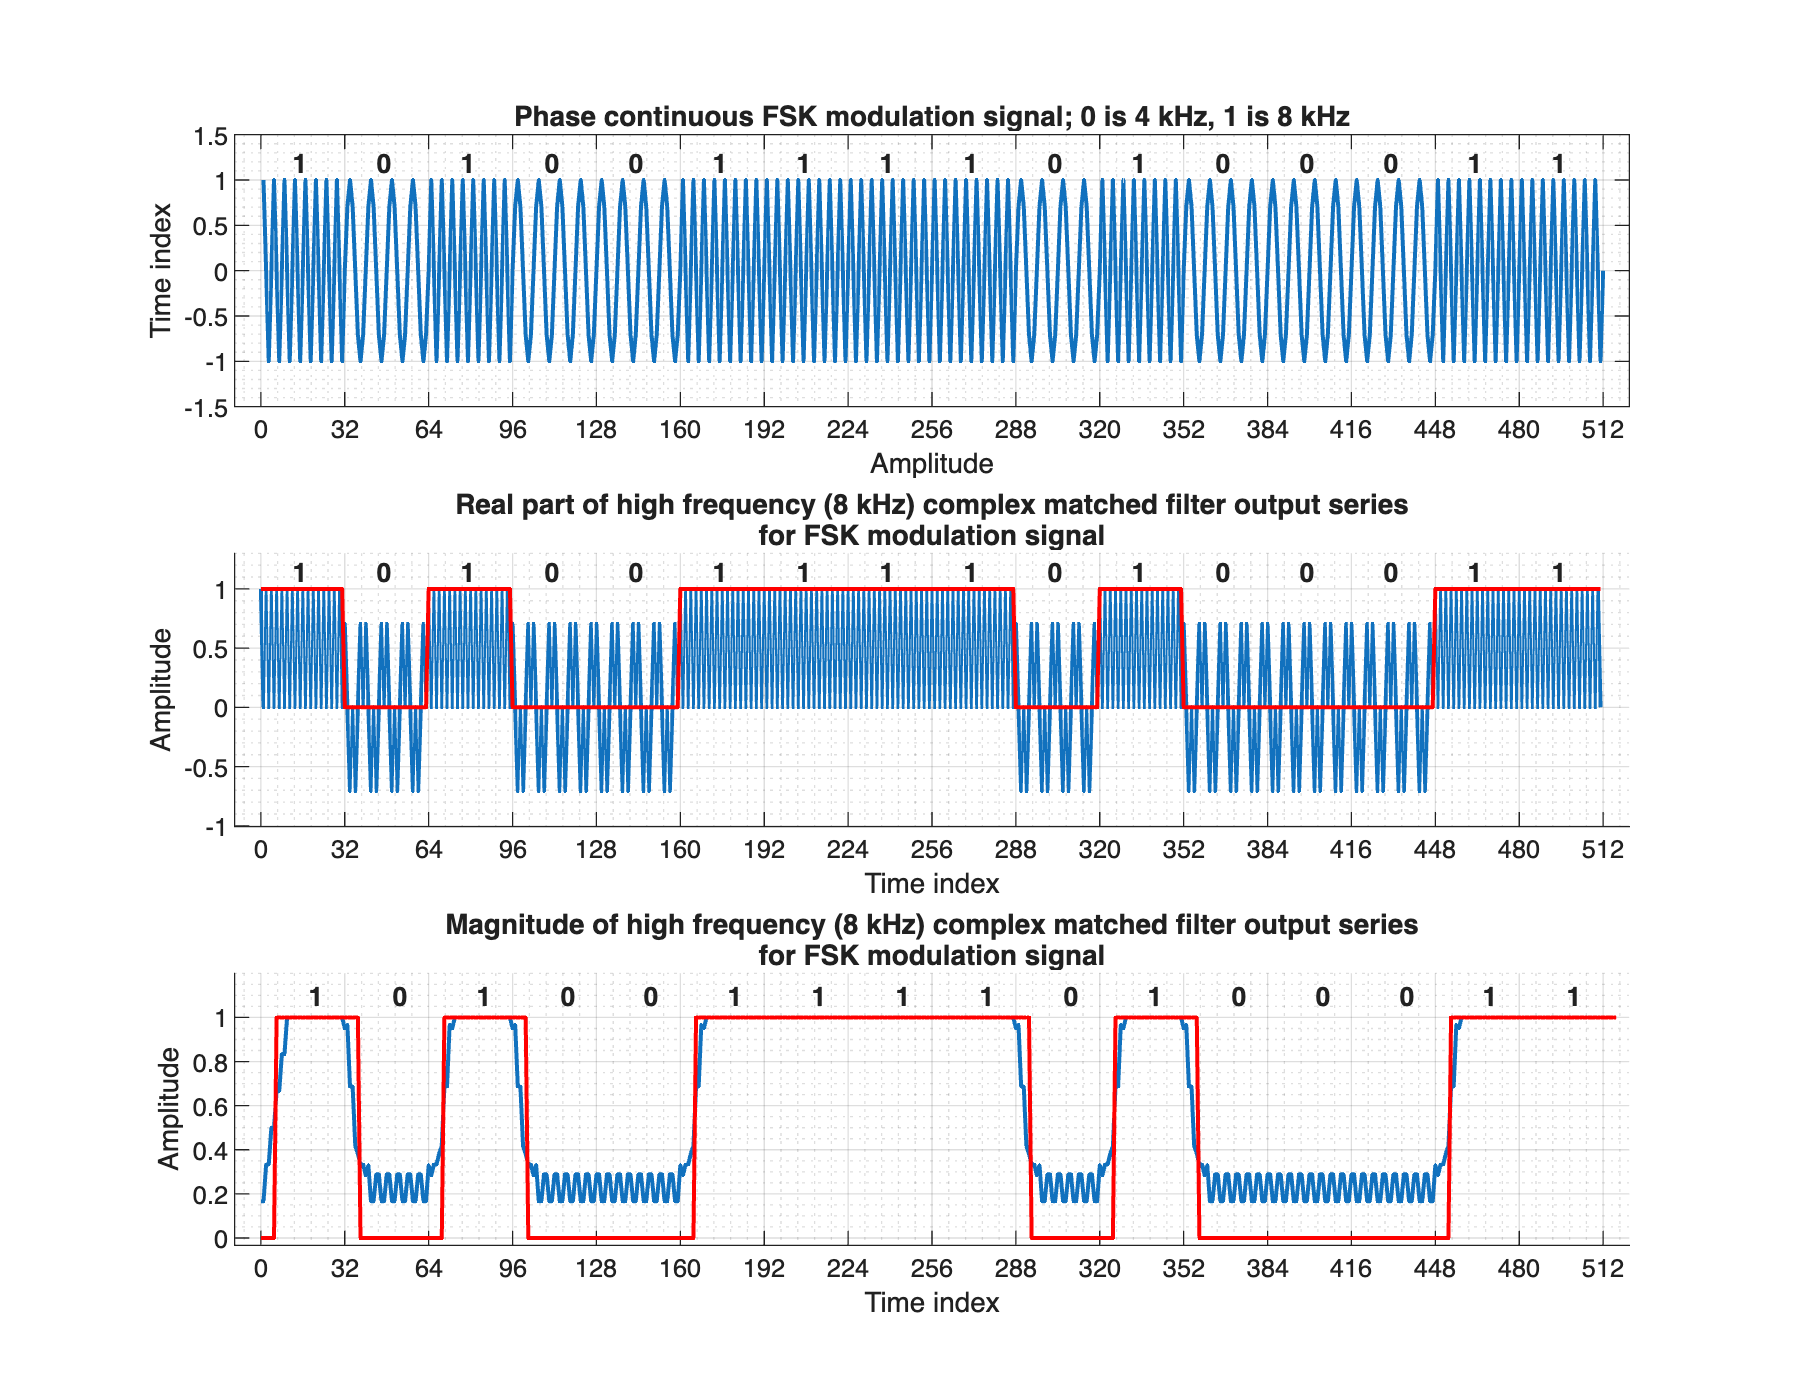


figure("Position", [0 0 900 700]);
subplot(3, 1, 1);
plot(xx(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, -1.5, 1.5]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(xx) + 0.2) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i), y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title("Phase continuous FSK modulation signal; 0 is 4 kHz, 1 is 8 kHz");
xlabel("Amplitude"); ylabel("Time index");

subplot(3, 1, 2);
y = real(yy2);
DLY = 0;
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.3, max(y) + 0.3]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.15) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Real part of high frequency (%d kHz) complex matched filter output series", f1), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");

subplot(3, 1, 3);
y = abs(yy4_scaled);
DLY = 6; % Half of the length of box car average filter
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    sprintf(...
      "Magnitude of high frequency (%d kHz) complex matched filter output series", f1), ...
    "for FSK modulation signal"
  });
xlabel("Time index"); ylabel("Amplitude");

### Part 6

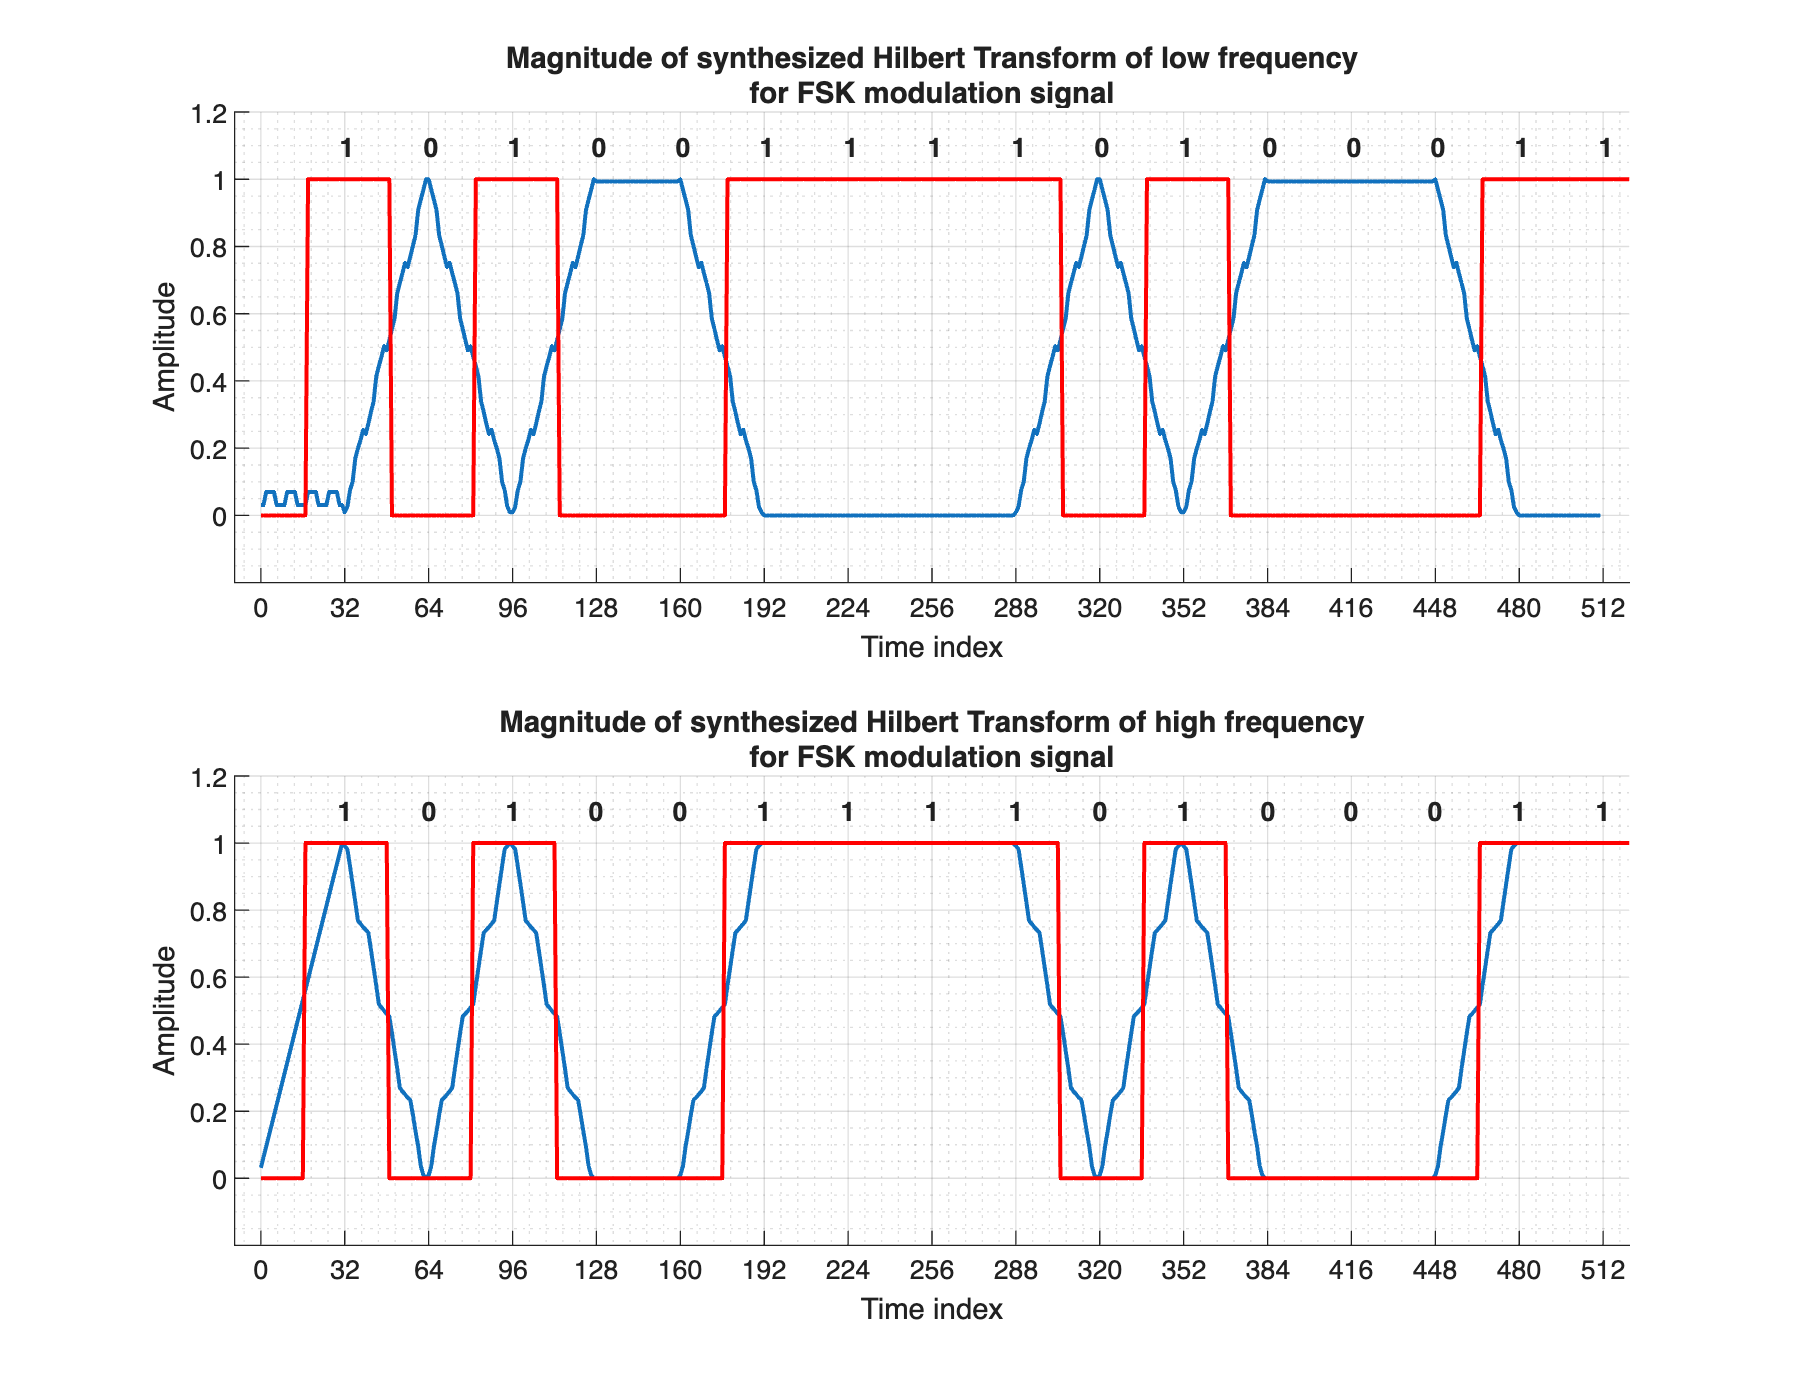

% An alternate detection scheme converts the output of the matched filters
% to their complex representation by using delays to form 90 deg phase shifted
% versions. We delay the 4-kHz tone 2 samples and the 8-kHz tone 1 samples to form
% yc1=[y1 zeros(1,2)]+j*[zeros(1,2) y1]; % synthetic Hilbert transform
% yc2=[y2 zeros(1,1)]+j*[zeros(1,1) y2]; % synthetic Hilbert transform
% The detected versions of the filter outputs are the magnitudes of these
% synthesized complex signals. We use time delay of 1/4 cycle per sinewave
% to synthesize a Hilbert transform)
% On two subplots plot the output series formed by the magnitude of the
% synthesized complex signals from filters h1 and h2. On the same subplots
% plot an overlay of the binary sequence (bb2) with a 2-sample and a
% 1-sample offset to align with the filter output series.

yc1 = [y1 zeros(1, 2)] + (1j * [zeros(1, 2) y1]); % synthetic Hilbert transform
yc2 = [y2 zeros(1, 1)] + (1j * [zeros(1, 1) y2]); % synthetic Hilbert transform

figure("Position", [0 0 900 700]);
% 16 (half of h1 length or matched filter length) +
% 2 from Hilbert transform
DLY = 2 + length(h1) / 2;
y = abs(yc1 / max(yc1));
subplot(2, 1, 1);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    "Magnitude of synthesized Hilbert Transform of low frequency", ...
    "for FSK modulation signal" ...
  });
xlabel("Time index"); ylabel("Amplitude");

y = abs(yc2 / max(yc2));
DLY = DLY - 1;
subplot(2, 1, 2);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    "Magnitude of synthesized Hilbert Transform of high frequency", ...
    "for FSK modulation signal" ...
  });
xlabel("Time index"); ylabel("Amplitude");

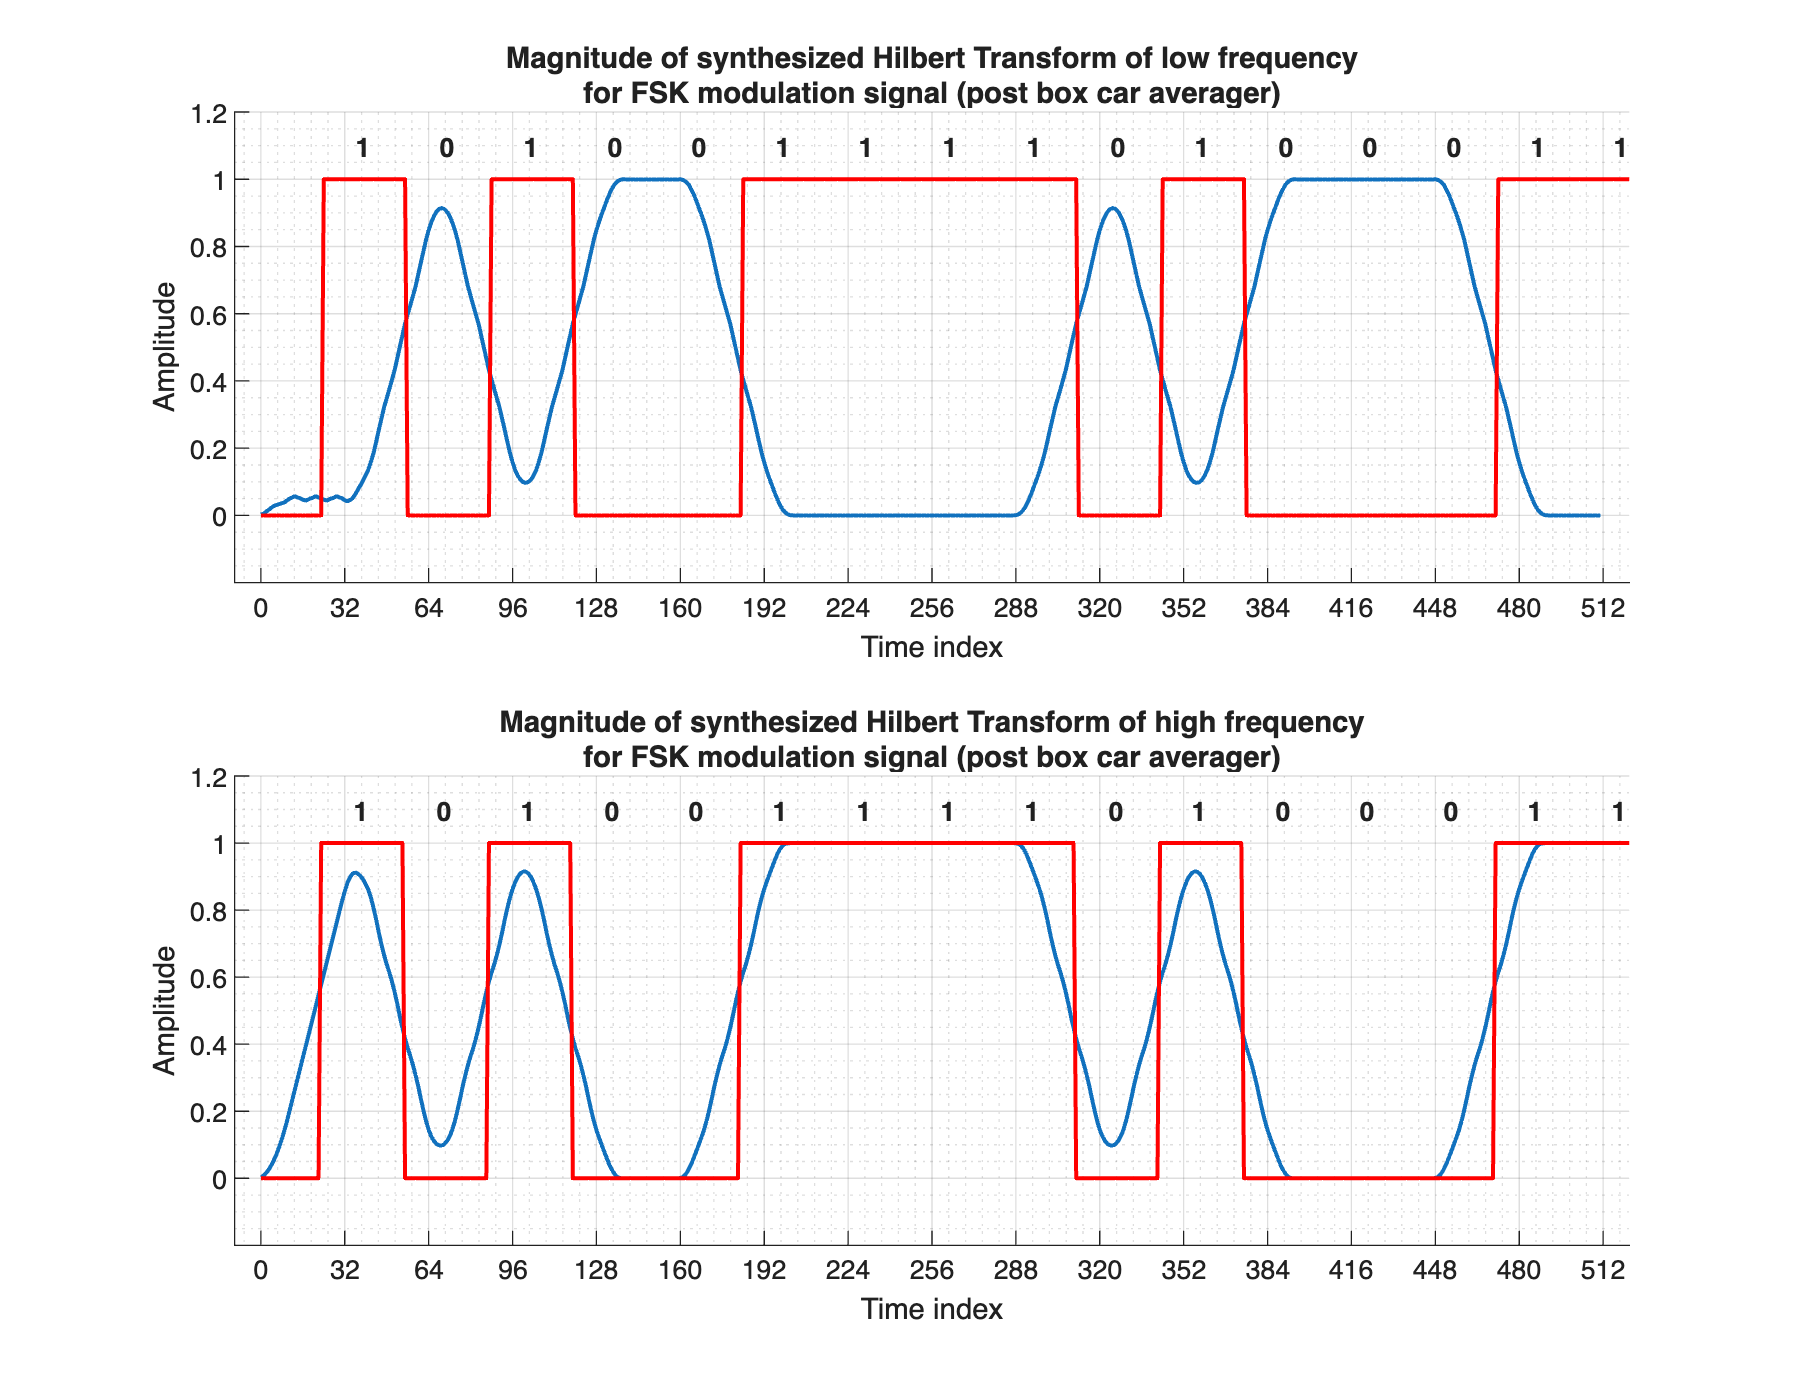


% Smooth out the output using a box-car averager
yc1_smooth = filter(h3, 1, abs(yc1));
yc2_smooth = filter(h3, 1, abs(yc2));

% Scale to unity gain
scl = max(yc1_smooth);
yc1_smooth_scaled = yc1_smooth / scl;

scl = max(yc2_smooth);
yc2_smooth_scaled = yc2_smooth / scl;

figure("Position", [0 0 900 700]);
% 16 (half of h1 length or matched filter length) +
% 6 (half of h3 length or box-car averaging filter length) + 2 from Hilbert
% transform
DLY = 2 + (length(h1) + length (h3)) / 2;
y = yc1_smooth_scaled;
subplot(2, 1, 1);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    "Magnitude of synthesized Hilbert Transform of low frequency", ...
    "for FSK modulation signal (post box car averager)" ...
  });
xlabel("Time index"); ylabel("Amplitude");

y = yc2_smooth_scaled;
DLY = DLY - 1;
subplot(2, 1, 2);
hold on;
plot(0 : PLOT_MAX_LEN - 1, y(1 : PLOT_MAX_LEN), "LineWidth", 1.5);
plot(...
  (0 : PLOT_MAX_LEN - 1 + DLY), ...
  [zeros(1, DLY), bb2(1 : PLOT_MAX_LEN)], ...
  "r", "LineWidth", 1.5);
hold off;
grid on; grid minor;
axis([-10, PLOT_MAX_LEN + 10, min(y) - 0.2, max(y) + 0.2]);
xticks(0 : UPSAMPLE_RATIO : PLOT_MAX_LEN);
% Note the bit values in the plot
x = ((UPSAMPLE_RATIO / 2) - 1) : UPSAMPLE_RATIO : PLOT_MAX_LEN - (UPSAMPLE_RATIO / 2);
y = (max(y) + 0.1) * ones(1, PLOT_MAX_LEN / UPSAMPLE_RATIO);
for i = 1 : length(x)
  text(...
    x(i) + DLY, y(i), num2str(bb1(i)), ...
    "FontWeight", "bold", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle");
end
title(...
  {...
    "Magnitude of synthesized Hilbert Transform of high frequency", ...
    "for FSK modulation signal (post box car averager)" ...
  });
xlabel("Time index"); ylabel("Amplitude");